# 直线拟合 linefit

%创造原始数据点 x y
x = 0:1:10;
n = rand(1, length(x)).*4 - 2;
y = 2*x + 1 + n;

%用直线拟合，获得参数 k b
[k, b, sst, sse, ssr, r2] = linefit(x, y)

k = 1.9748

b = 1.2690

sst = 436.1212

sse = 7.1527

ssr = 428.9685

r2 = 0.9836

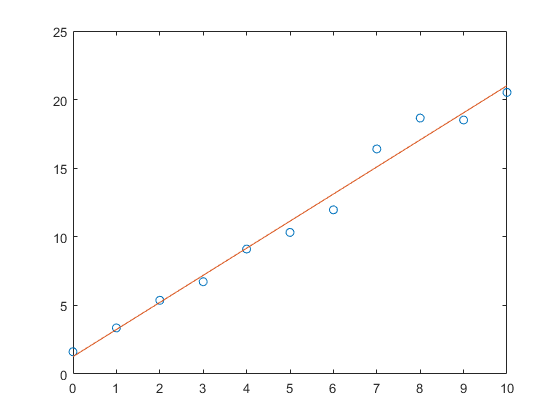


%绘图
fity = k.*x + b;
figure;
plot(x, y, 'o', x, fity);

# 曲线拟合 polyfit

%创造原始数据点 x y
x = 0:1:10;
n = rand(1, length(x)).*4 - 2;
y = 2*x + 1 + n;

%使用曲线拟合 polyfit
p = polyfit(x, y, 1);
y1 = polyval(p, x);

%计算拟合优度R²
r2 = rsquare(y, y1)

r2 = 0.9709

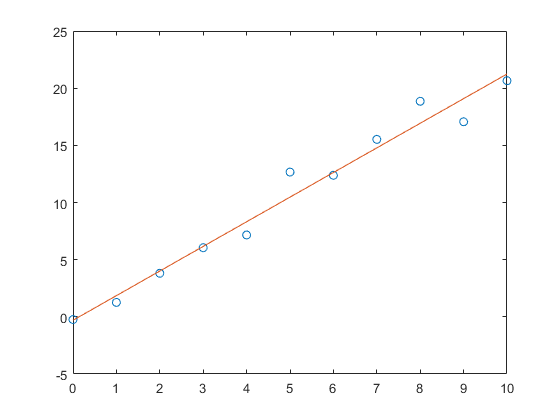


%绘图
figure;
plot(x, y, 'o', x, y1)

# 计算拟合优度 R²

%创造原始数据点 x y
x = 0:1:10;
n = rand(1, length(x)).*4 - 2;
y = 2*x + 1 + n;

%使用曲线拟合 polyfit
p = polyfit(x, y, 1);
y1 = polyval(p, x);

%计算拟合优度R²
r2 = rsquare(y, y1)

r2 = 0.9604